# Lab 5 - Higgs Classification

Thomas Conaway

Lab Partners Jeff Jiang, Avis Soval

Time: 13 hours

We will be using simulated data to look for the standard model Higgs boson that results from proton-proton collisions at $\sqrt{\;s}=13\;\mathrm{TeV}$ (an observer-independent measure of how hard the protons hit). The resulting Higgs bosons quickly decay into a bottom quark-anti quark pairs. In quantum chromodynamics (QCD) colored objects like quarks cannot exist freely and so they create other colored objects which travel with them to form colorless ensembles. This hadronization of the quarks creates cones of particles called jets. Using Calorimeters we can collect the information needed to reconstruct a Higgs candidate as a large-radius jet from these smaller ones.

The QCD background is capable of producing a significant number of b quarks in jets which contaminate the background and make it impossible to directly confirm a 5-sigma observation for this decay process (described as a gluon fusion production mode, or "ggF"). However, Higgs bosons produced with high transverse momentum are believed to resolve this complication and allow for greater discovery sensitivity.

clc; clear; close all;
% signal dataset is labelled higgs, background dataset is labeled "qcd"
h5disp("higgs_100000_pt_1000_1200.h5");

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("qcd_100000_pt_1000_1200.h5");

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


signaldata1 = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
bgdata1 = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

The data labelled 'higgs' represents jets from a Higgs decay. The data labelled 'qcd' represents jets from the quantum chromodynamics (QCD) background. The QCD background are the other particles created by the hadronic jets that make it harder to identify the Higgs.  These simulated samples are representative of a binary classification problem with classes 'higgs' and 'qcd'.

Each row contains a different recorded jet feature, 14 in total. They are: **'pt'**,** 'eta'**, **'phi**',** 'mass'**,** 'ee2'**,** 'ee3'**,** 'd2'**,** 'angularity'**, **'t1'**, **'t2'**, **'t3'**, **'t21'**, **'t32'**,** 'KtDeltaR'**.

**'pt' **: the 'transverse momentum" $p_T$ of the jet (perpendicular to beam line) in GeV. This data set is a collection of those in the range of 1000 GeV to 1200 GeV. Momentum along beam line (parallel) may be left over from the beam itself, so high perpendicular suggests a clean, hard collision, making the event a candidate of interest. A higher tranverse momentum means it is likely to be a Higgs jet, provided that other conditions are also met.

**'eta'** : the "pseudorapidity" $\eta$ is a spatial coordinate decribing the angle of a particle relative to the beam axis. Values range from -4 to 4, with 0 is along beam axis and -4 or 4 is  perpendicular.

**'phi'** : the "azimuth" $\phi$ is another spatial coordinate like pseudorapidity.

**'mass'** : the jet mass $m$ in GeV. The invariant mass formula is $E^2 =P^2 +m^2$.

**'ee2'** : the 2-point ECF (energy correlation function) ratio $e_2$.

**'ee3'** : 3-point ECF ratio $e_3$.

**'d2'** : 3-to 2-point ECF ratio $D_2$.

**'angularity'** : $\tau {\;}_2$ describes the orientation between planes or similar features.

**'t1'**,** 't2'**, **'t3'** : are subjettiness (jet shape) observables $\tau {\;}_1 ,\tau {\;}_2 ,\tau {\;}_3$. Describes internal features within a jet that allows for determining the originating object.

**'t21'** : the N-subjettiness observable $\frac{\tau {\;}_2 }{\tau {\;}_1 }$. Used for identifying two-prong objects like boosted W, Z, and Higgs bosons.

**'t32'** : the N-subjettiness observable $\frac{\tau {\;}_3 }{\tau_2 }$ (or written $\tau {\;}_{3,2}^{\left(\beta \;\right)}$). One of the most effective discriminants for three-prong objects like boosted top quarks against the QCD background.

**'KtDeltaR'** : is used in jet reconstruction. R is a parameter of the $k_T$ jet finding algorithms for hadron-hadron collisions.

We will be looking for discriminating power between the signal and background by making histograms for each feature.

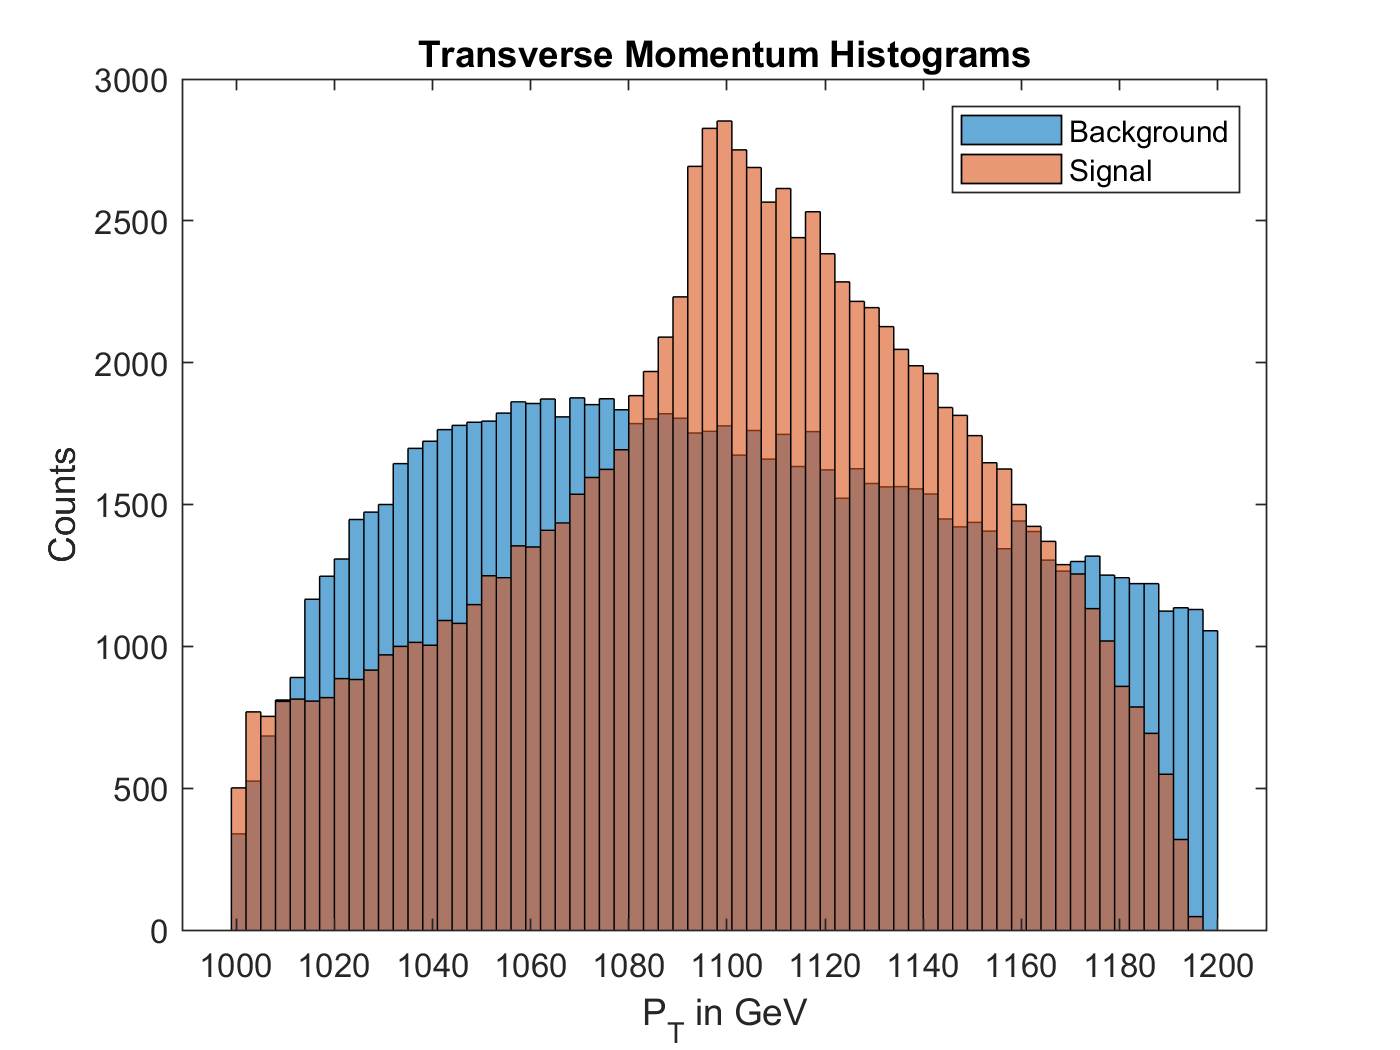

close all;
histogram(bgdata1(1,:)), hold on, histogram(signaldata1(1,:)), title("Transverse Momentum Histograms");
legend("Background","Signal"), xlabel("P_T in GeV"), ylabel("Counts"), hold off;

The histogram distribution of transverse momentum within the 1000-1200 interval. Cause of shapes unclear. Signal rises to a peak at 1100 GeV and falls off sharply as it increases to 1200.

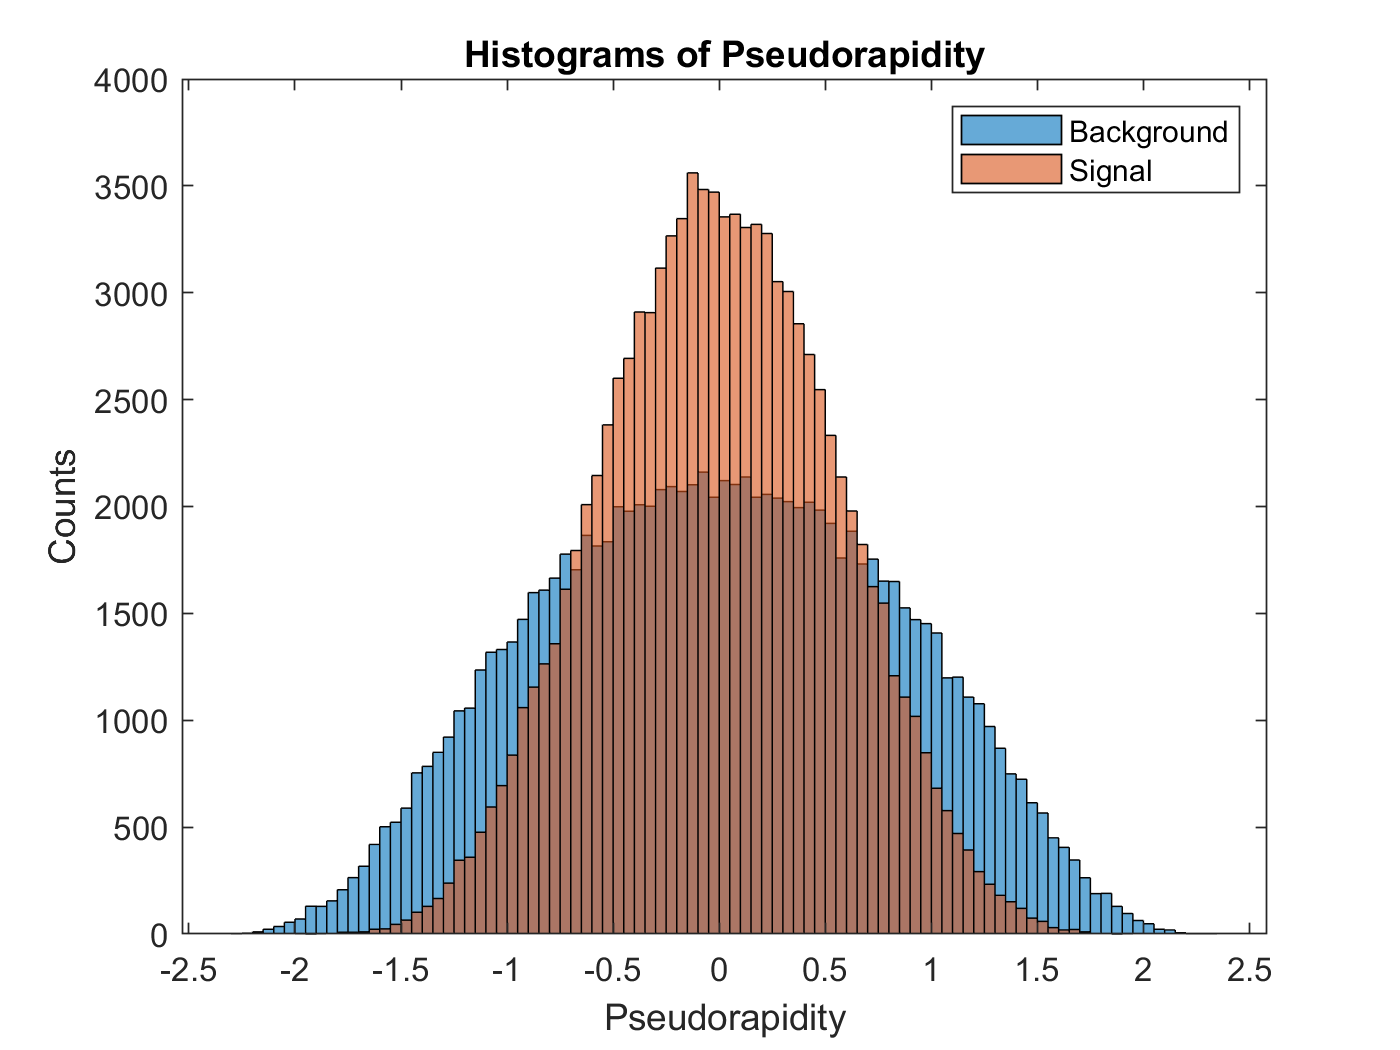

histogram(bgdata1(2,:)), hold on, histogram(signaldata1(2,:)), title("Histograms of Pseudorapidity");
legend("Background","Signal"), xlabel("Pseudorapidity"), ylabel("Counts");
hold off;

The pseudorapidity appears to be Gaussian distributed centered at 0 (no deflection from beam axis). The Higgs jet distribution is slightly narrower.

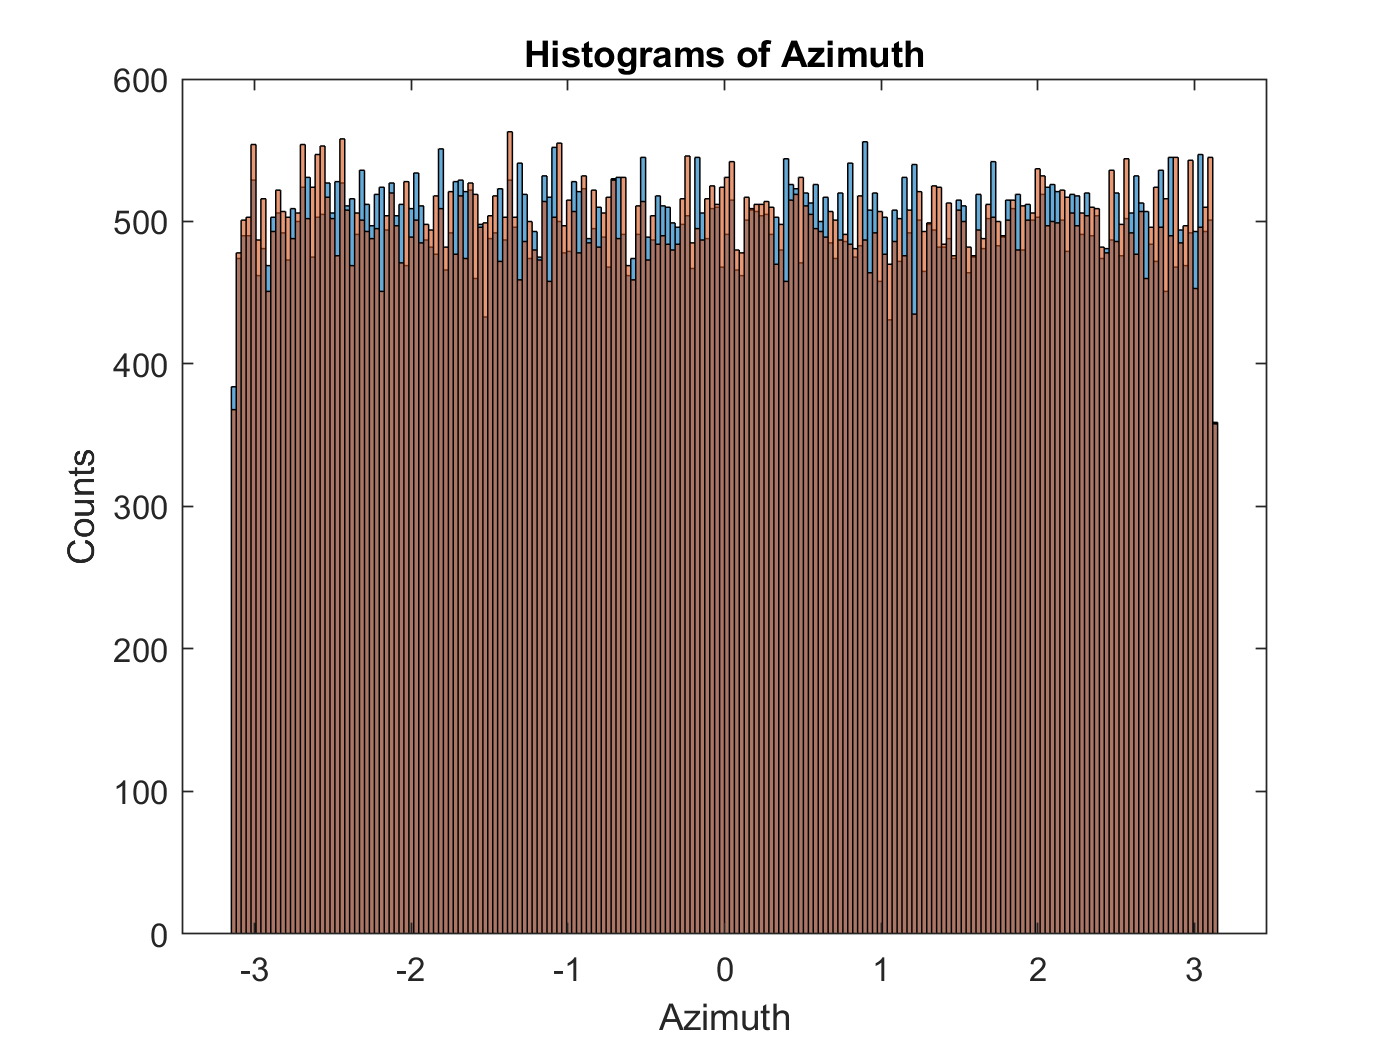

histogram(bgdata1(3,:),200);
hold on,
histogram(signaldata1(3,:),200);
title("Histograms of Azimuth"), xlabel("Azimuth"), ylabel("Counts");
hold off;

There appears to be no discriminating features between the background and signal for the azimuth. They almost overlap completely except for some small noise.

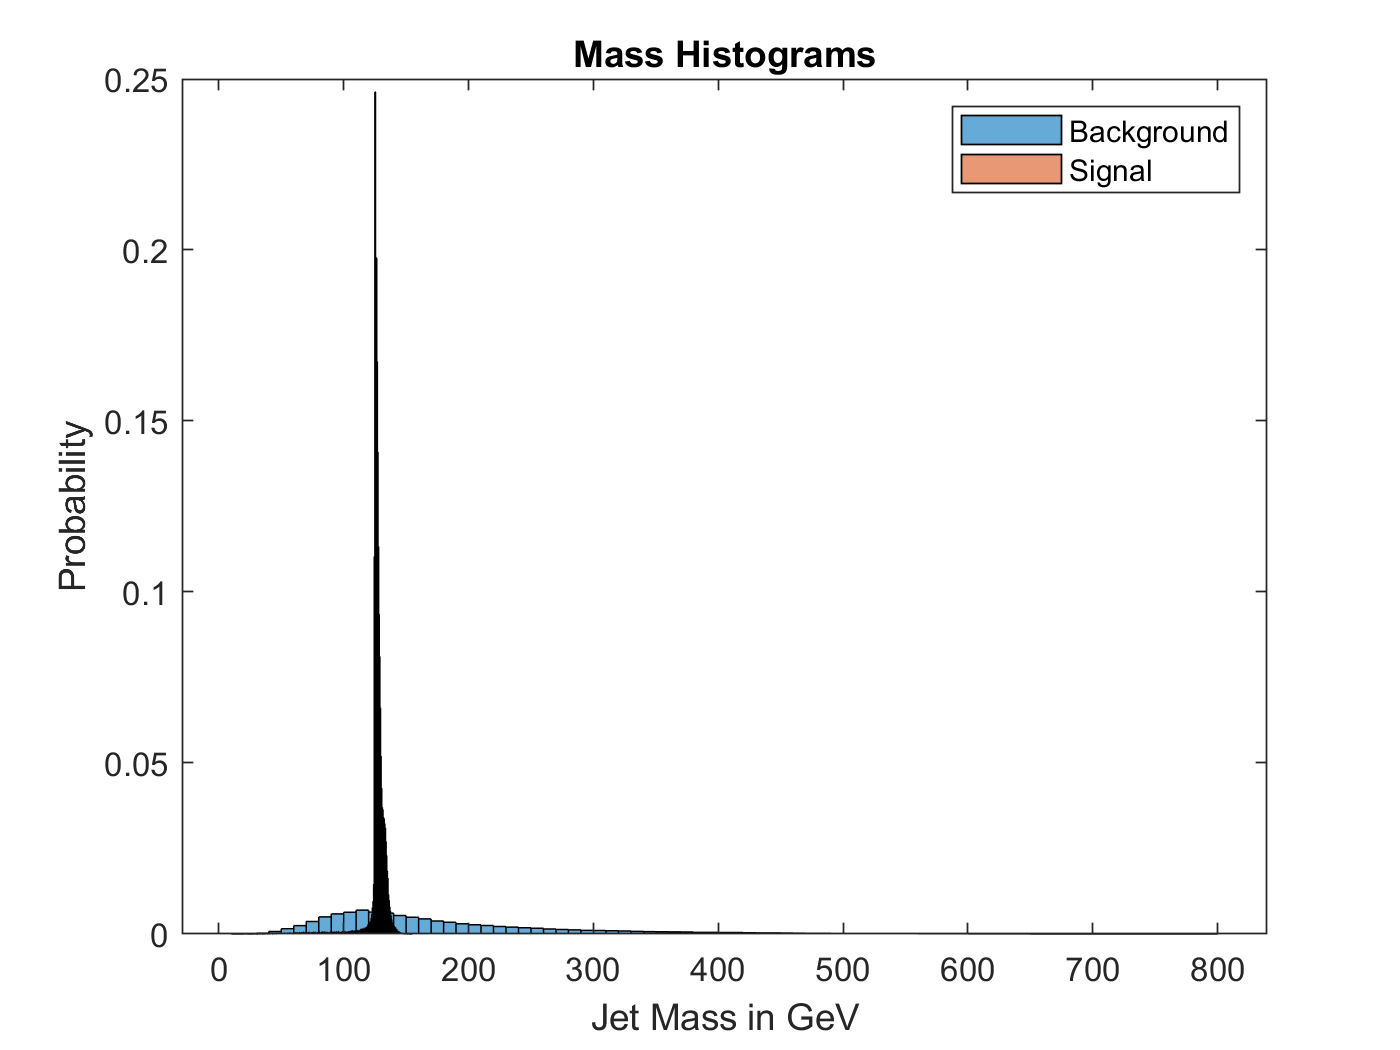

% binsw = 0:5:800; % helps with comparison, ,"Normalization","pdf" also works
histogram(bgdata1(4,:),"Normalization","pdf"), title("Mass Histograms"), ylabel("Probability"), hold on;
histogram(signaldata1(4,:),"Normalization","pdf"), legend("Background","Signal"), xlabel("Jet Mass in GeV"), hold off;

Masses of the Higgs jet data are tightly centered at about 125 GeV, which is the expected mass for the Higgs. Background is more spread out and is capable of producing much higher mass jets. Background shape and smoothness suggests it may be following some probability distribution that we can look for. Taking a closer look at the mass histograms:

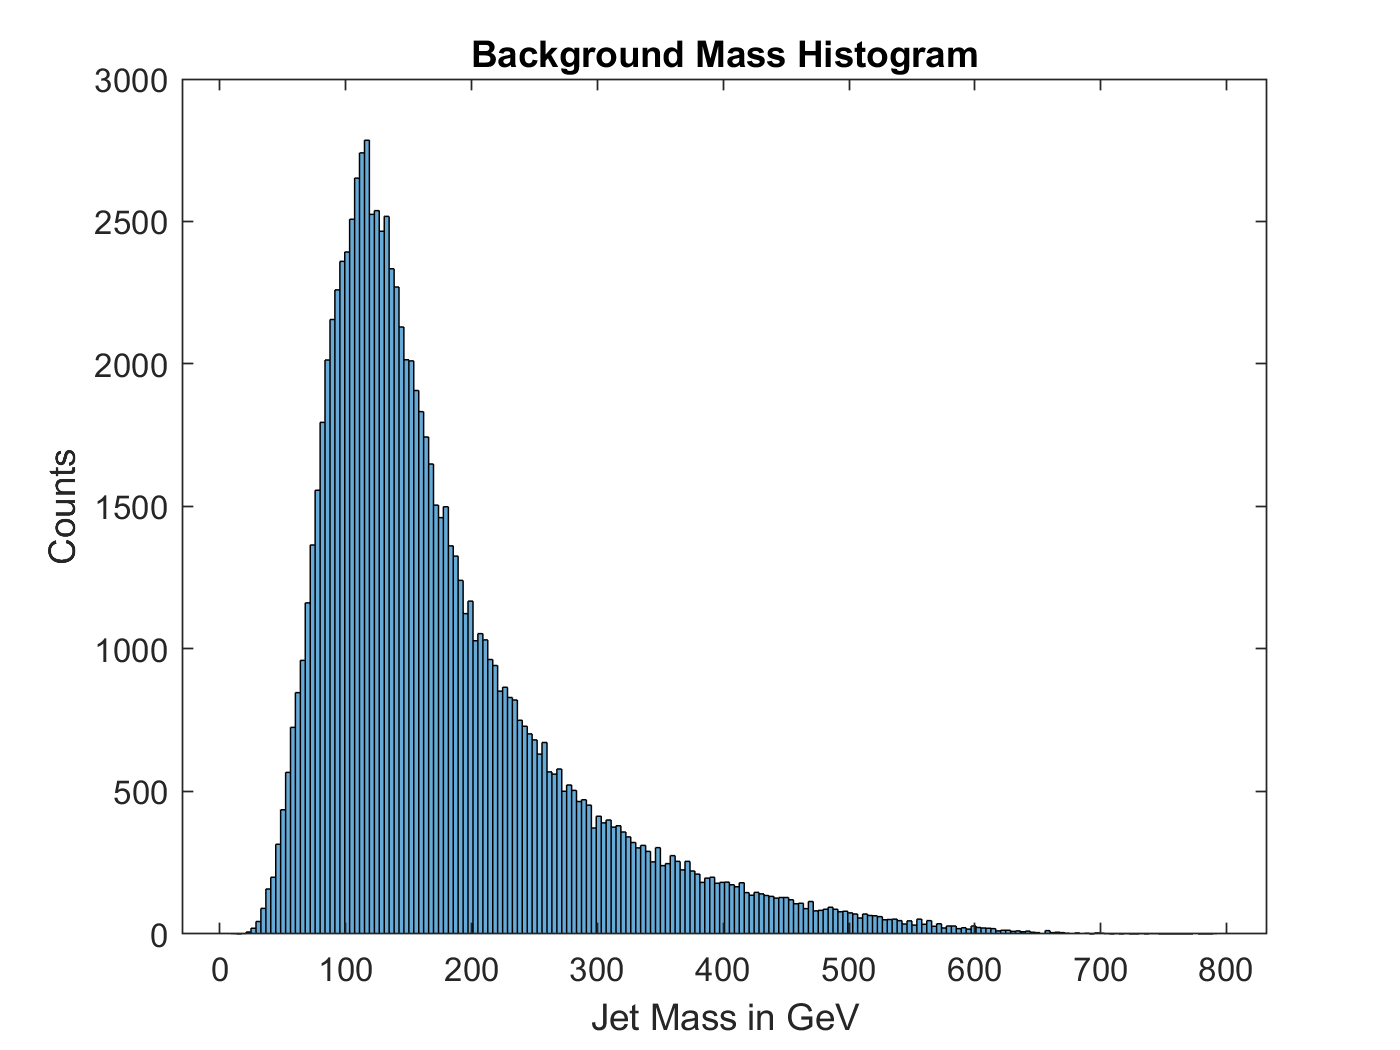

histogram(bgdata1(4,:),200), title("Background Mass Histogram"), xlabel("Jet Mass in GeV"), ylabel("Counts");

% log of input almost is something

The smoothness of the background mass suggests it may be following some asymetric distribution.

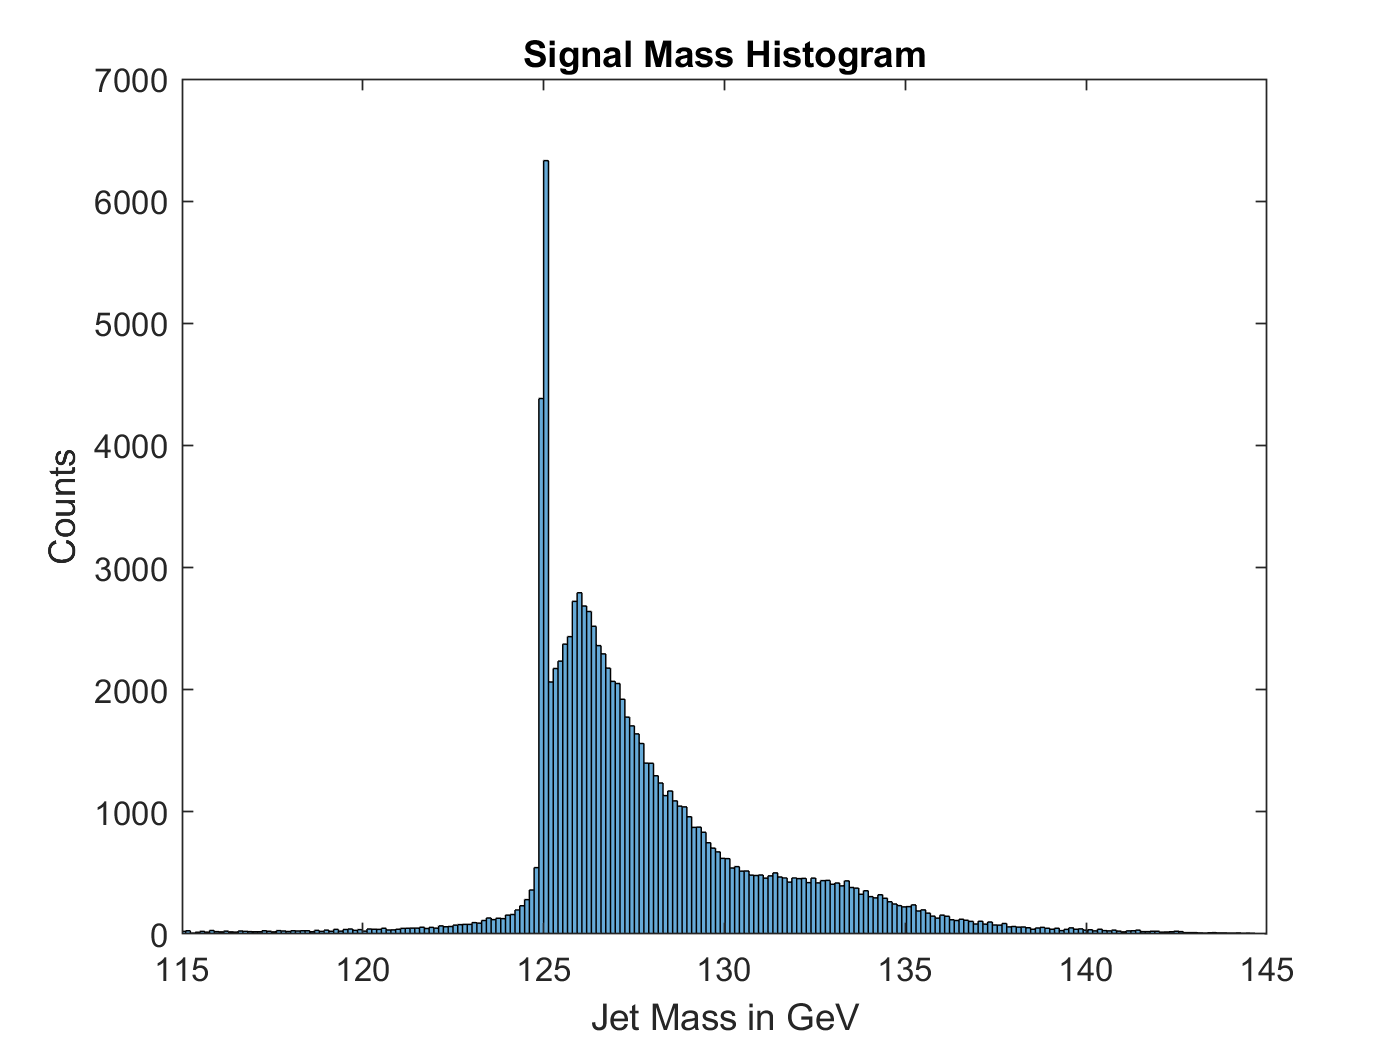

histogram(signaldata1(4,:),1000), xlim([115,145]), title("Signal Mass Histogram"), xlabel("Jet Mass in GeV"), ylabel("Counts");

Fine histogram bins of the signal show that it is sharply peaked at 125, with a smaller second peak at 126. There is a range of values from 125 to 135 with some trailing edges. PDGLive has the Higgs mass listed as 125.10 +/- 0.14 GeV. If the signal data truly is just the Higgs jetts then while a mass of 125 is a candidate for the Higgs other values should still be allowed pending other criteria. The signal falls in the center of the background. The signal's second peak at 126 GeV almost looks like the shape of the background and may be of interest if not a coincidence.

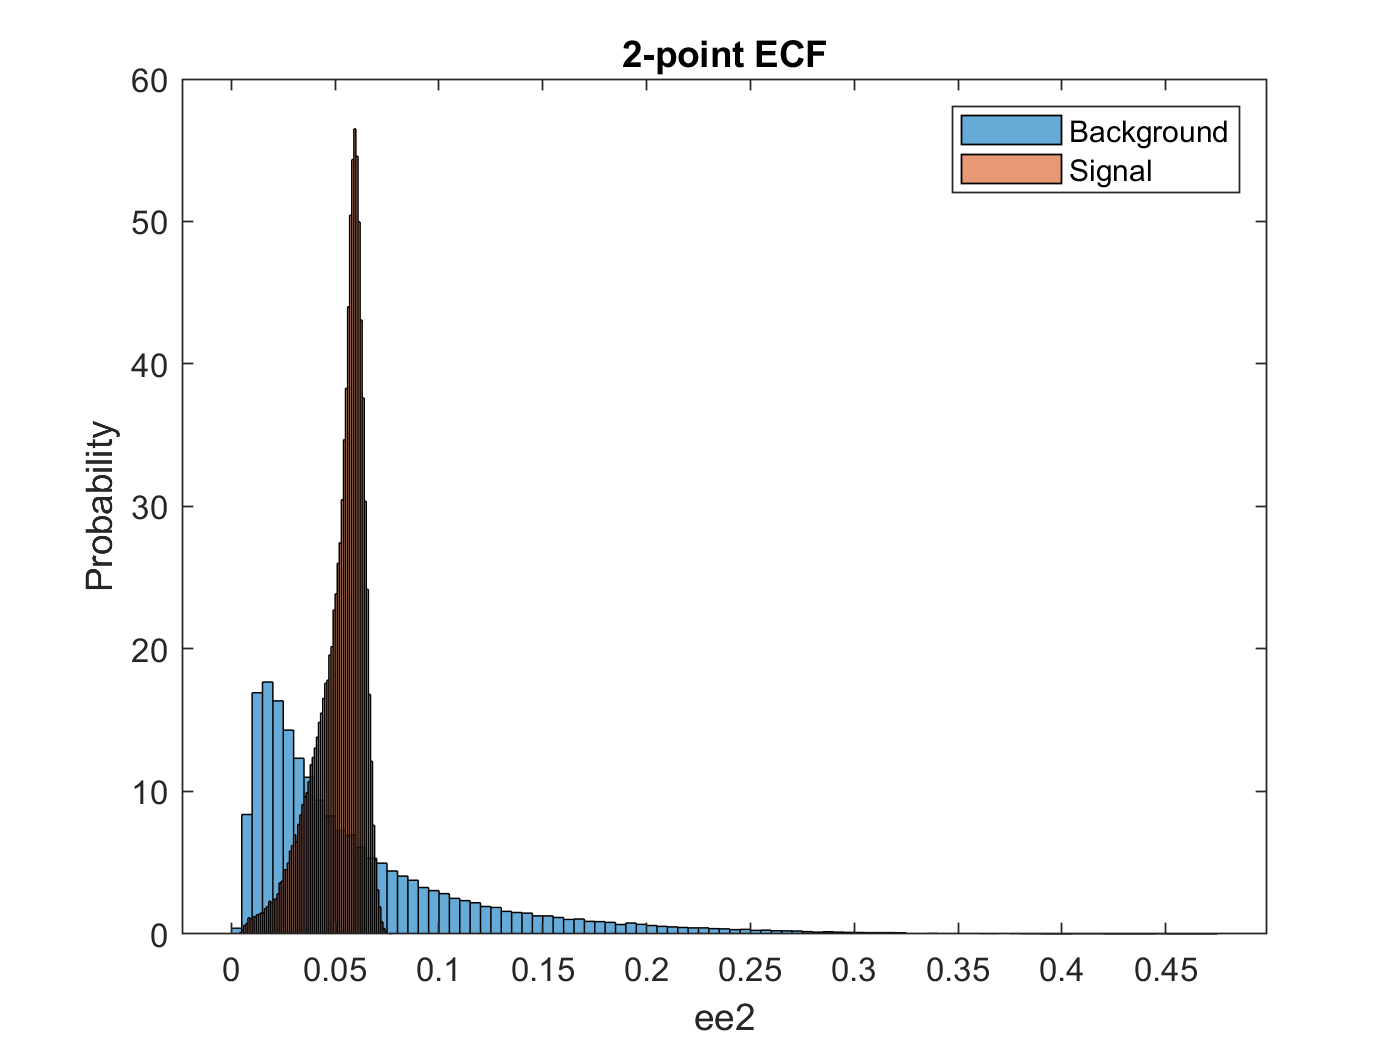

close all hidden;
histogram(bgdata1(5,:),"Normalization","pdf"), hold on, histogram(signaldata1(5,:),"Normalization","pdf");
title("2-point ECF"), xlabel("ee2"), ylabel("Probability"), legend("Background","Signal");
hold off;

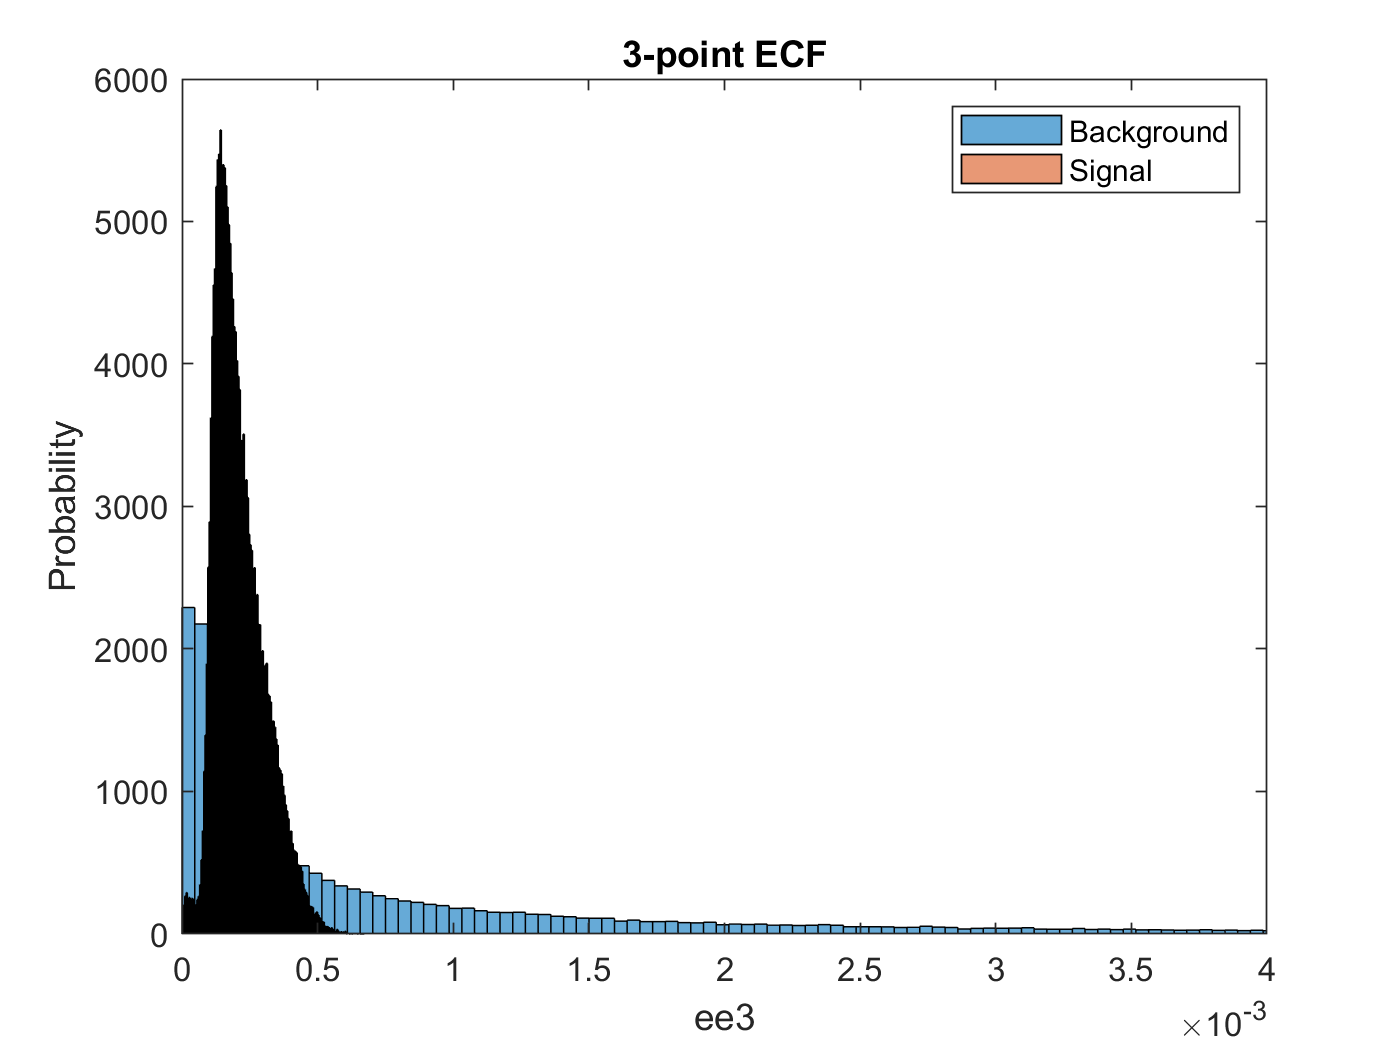

histogram(bgdata1(6,:),2000,"Normalization","pdf"), hold on;
histogram(signaldata1(6,:),"Normalization","pdf"), xlim([0,0.004]);
title("3-point ECF"), xlabel("ee3"), ylabel("Probability"), legend("Background","Signal");
hold off;

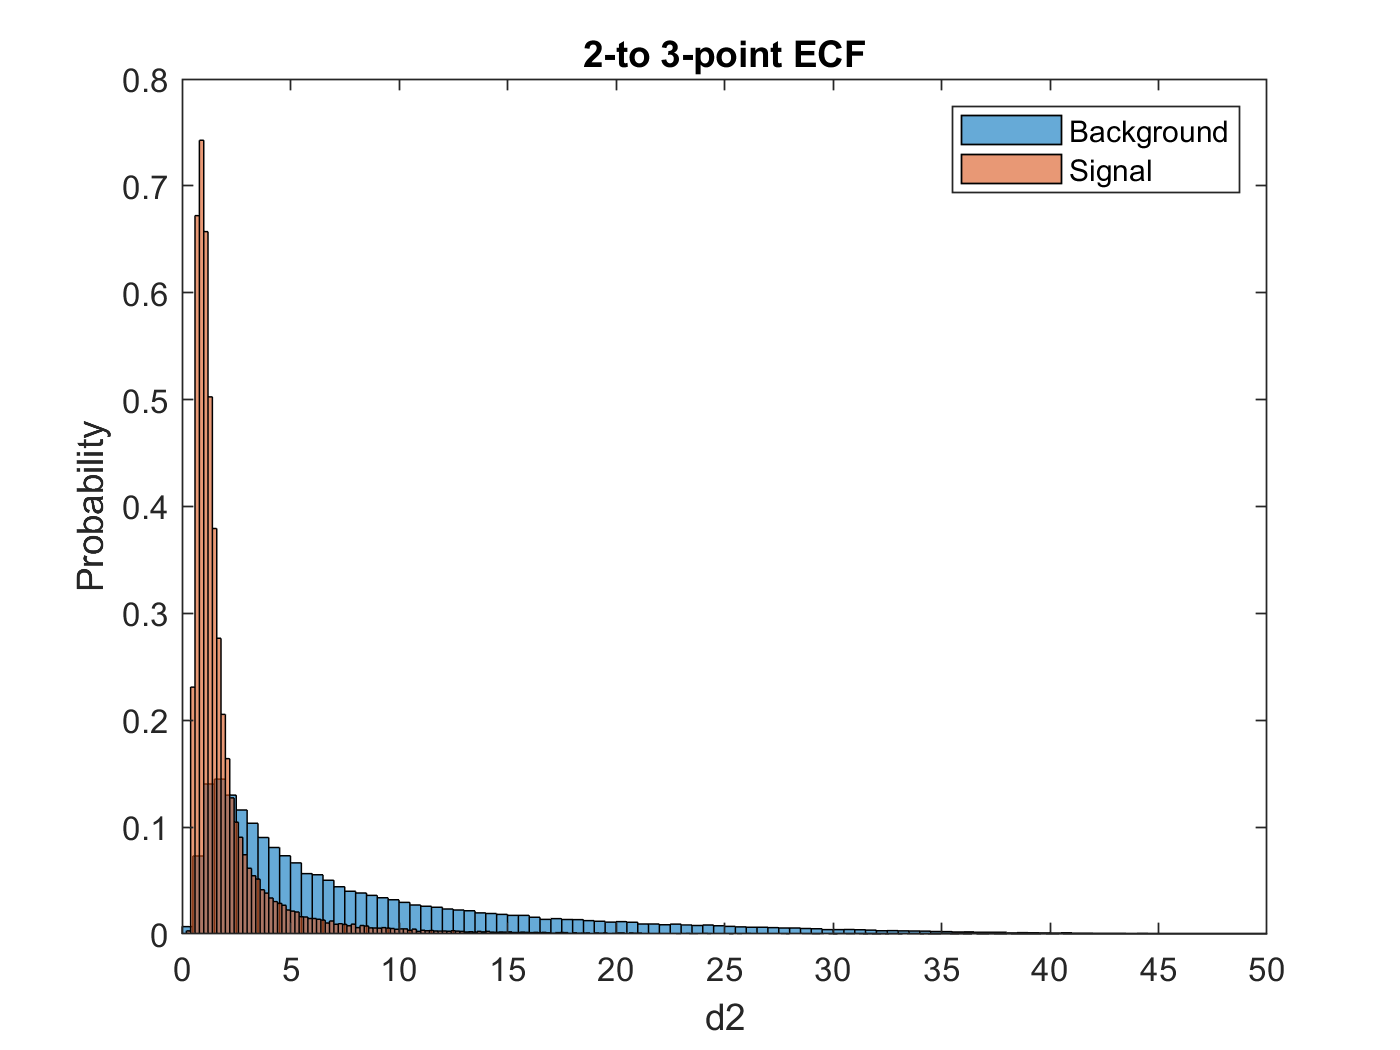

histogram(bgdata1(7,:),"Normalization","pdf"), hold on;
histogram(signaldata1(7,:),"Normalization","pdf"), xlim([0,50]);
title("2-to 3-point ECF"), xlabel("d2"), ylabel("Probability"), legend("Background","Signal");
hold off;

Energy correlation function graphs. Signal features are sharply peaked but all fall within the background. All but the ee2 signal distribution feature gradual decay for higher values. The ee2 signal shape is curiously reversed.

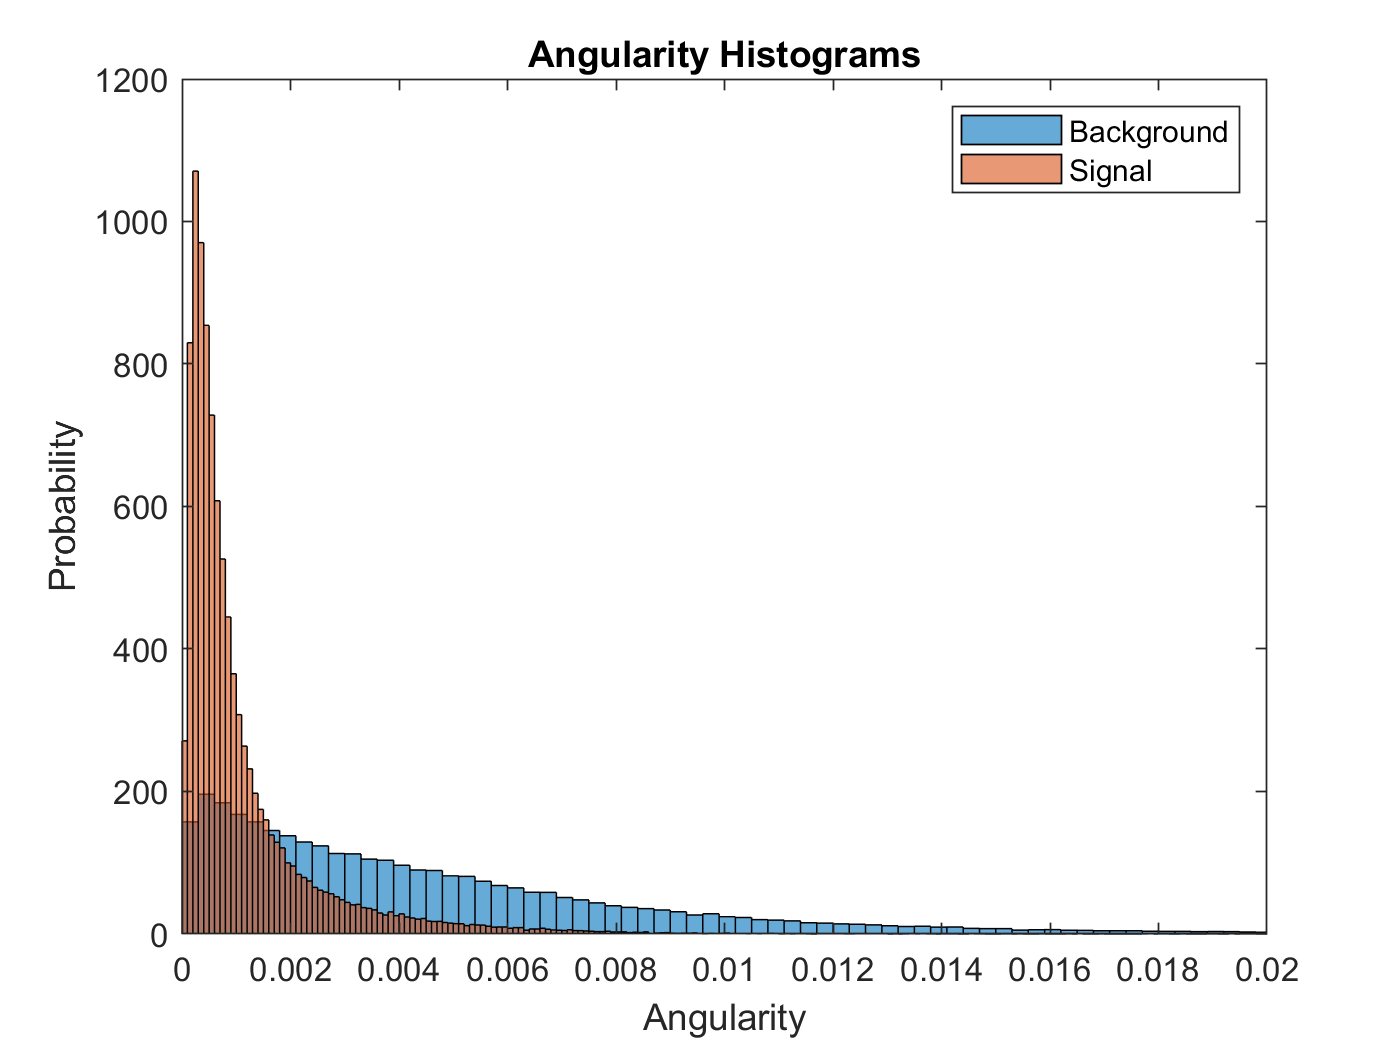

histogram(bgdata1(8,:),"Normalization","pdf"), hold on, histogram(signaldata1(8,:),"Normalization","pdf");
title("Angularity Histograms"), xlabel("Angularity"), ylabel("Probability"), xlim([0,0.02]);
legend("Background","Signal");
hold off;

The angularity value of the signal is much more sharply peaked near zero than the background.

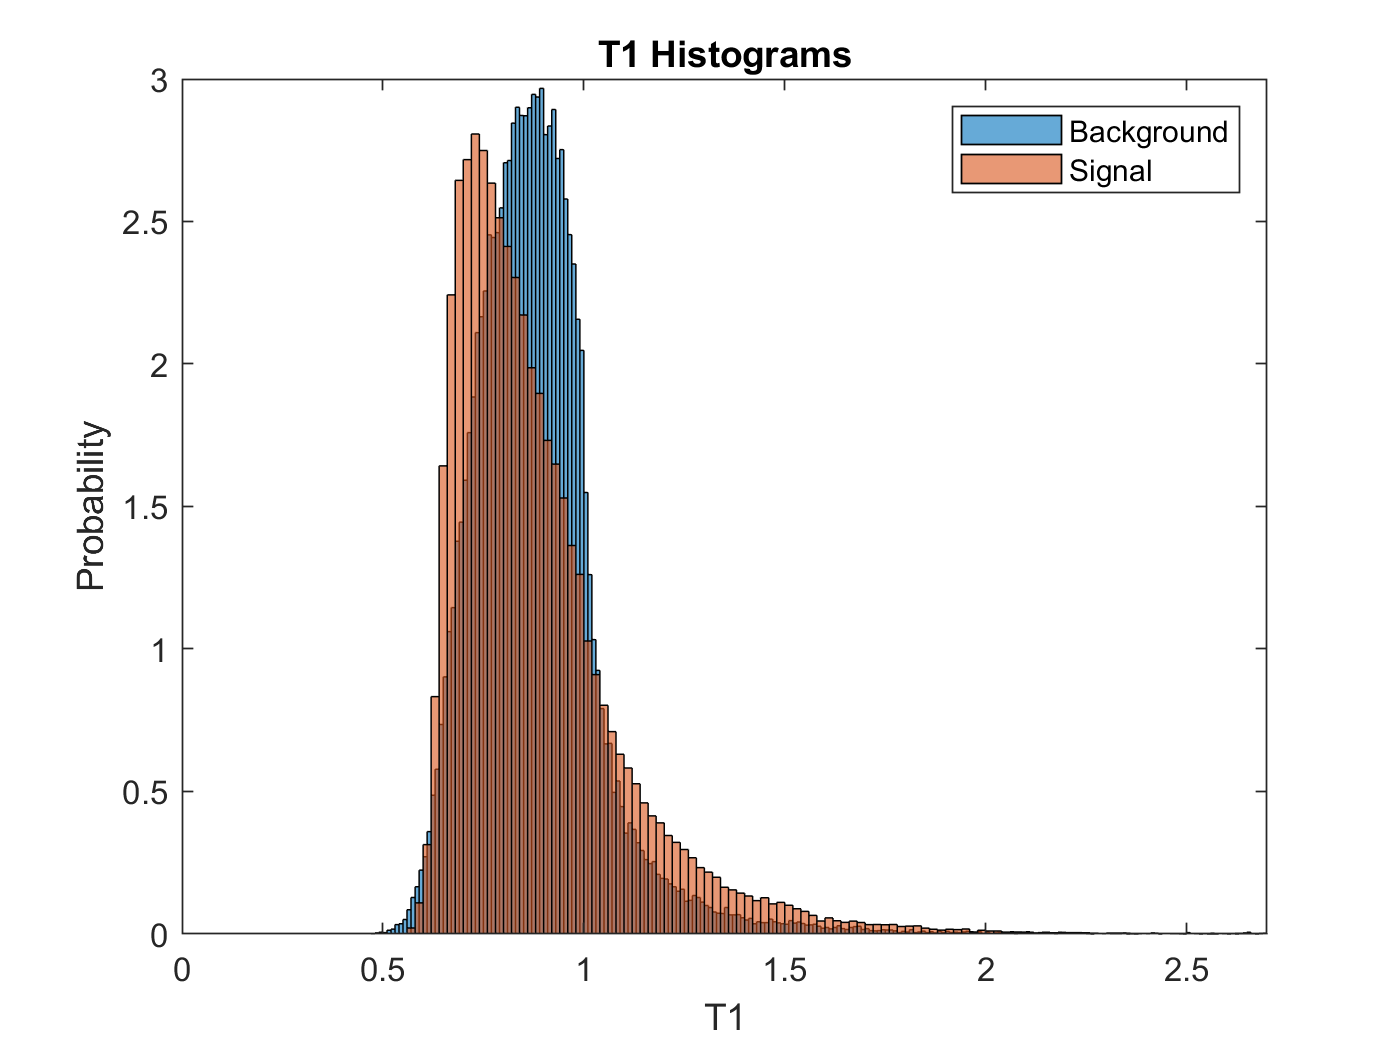

histogram(bgdata1(9,:),"Normalization","pdf"), hold on, histogram(signaldata1(9,:),"Normalization","pdf");
title("T1 Histograms"), xlabel("T1"), ylabel("Probability"), xlim([0,2.7]);
legend("Background","Signal");
hold off;

There is considerable overlap of the T1 histograms. The peaks are slightly off-center but are similarly shaped.

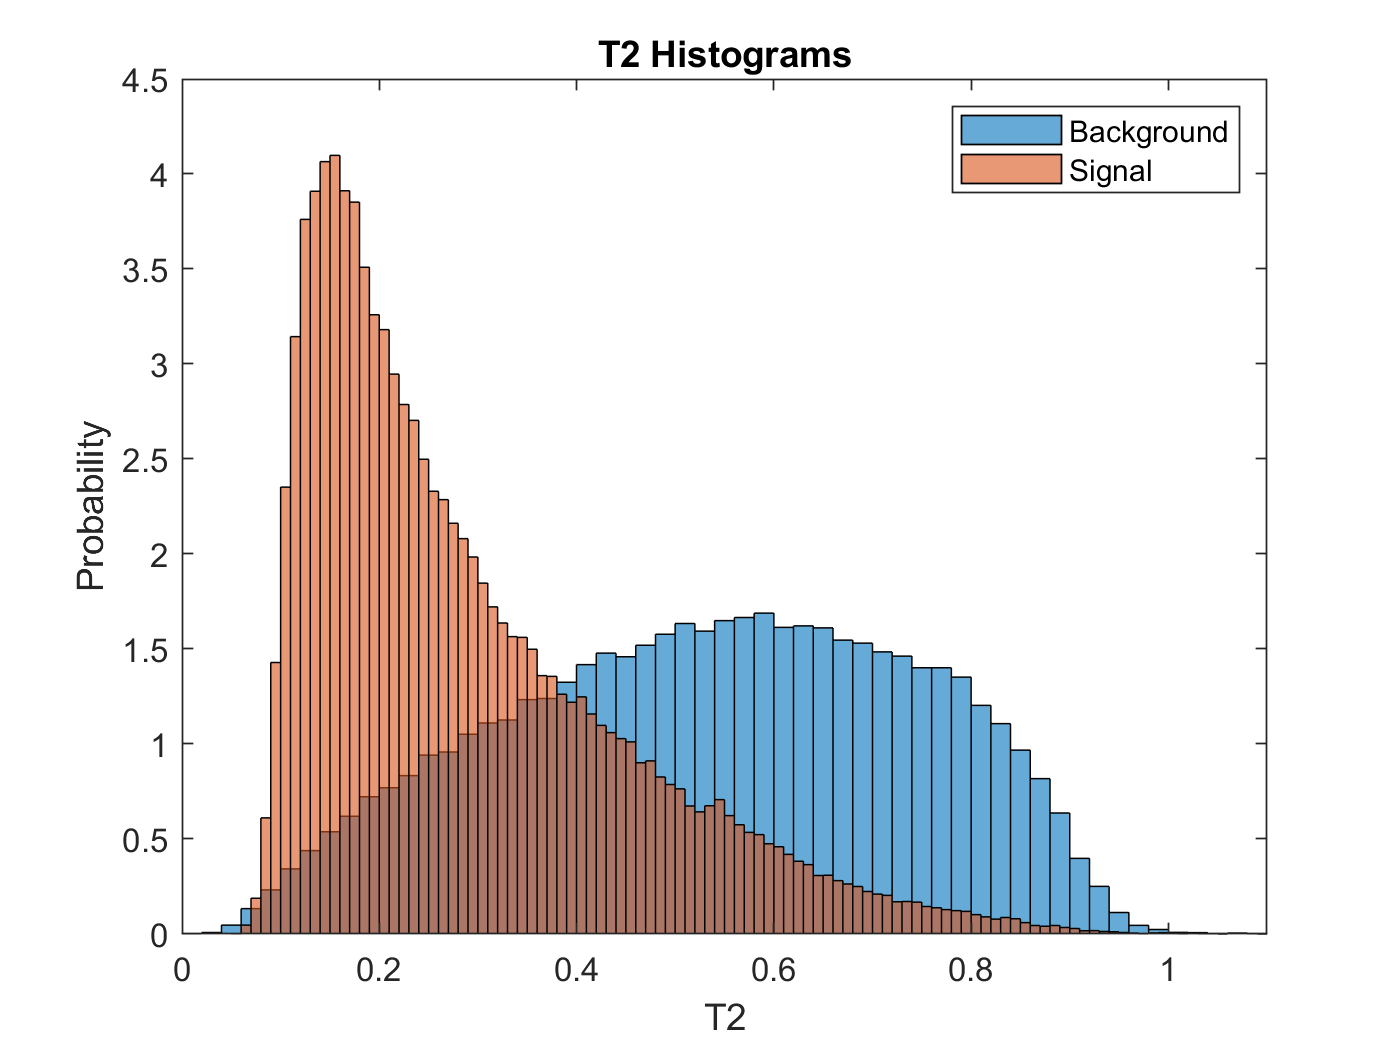

histogram(bgdata1(10,:),"Normalization","pdf"), hold on, histogram(signaldata1(10,:),"Normalization","pdf")
title("T2 Histograms"), xlabel("T2"), ylabel("Probability"), xlim([0,1.1]);
legend("Background","Signal");
hold off;

The T2 signal is sharply centerd at 0.15 and then decays off while the background hill is centered roughly over the entire range from 0 to 1.

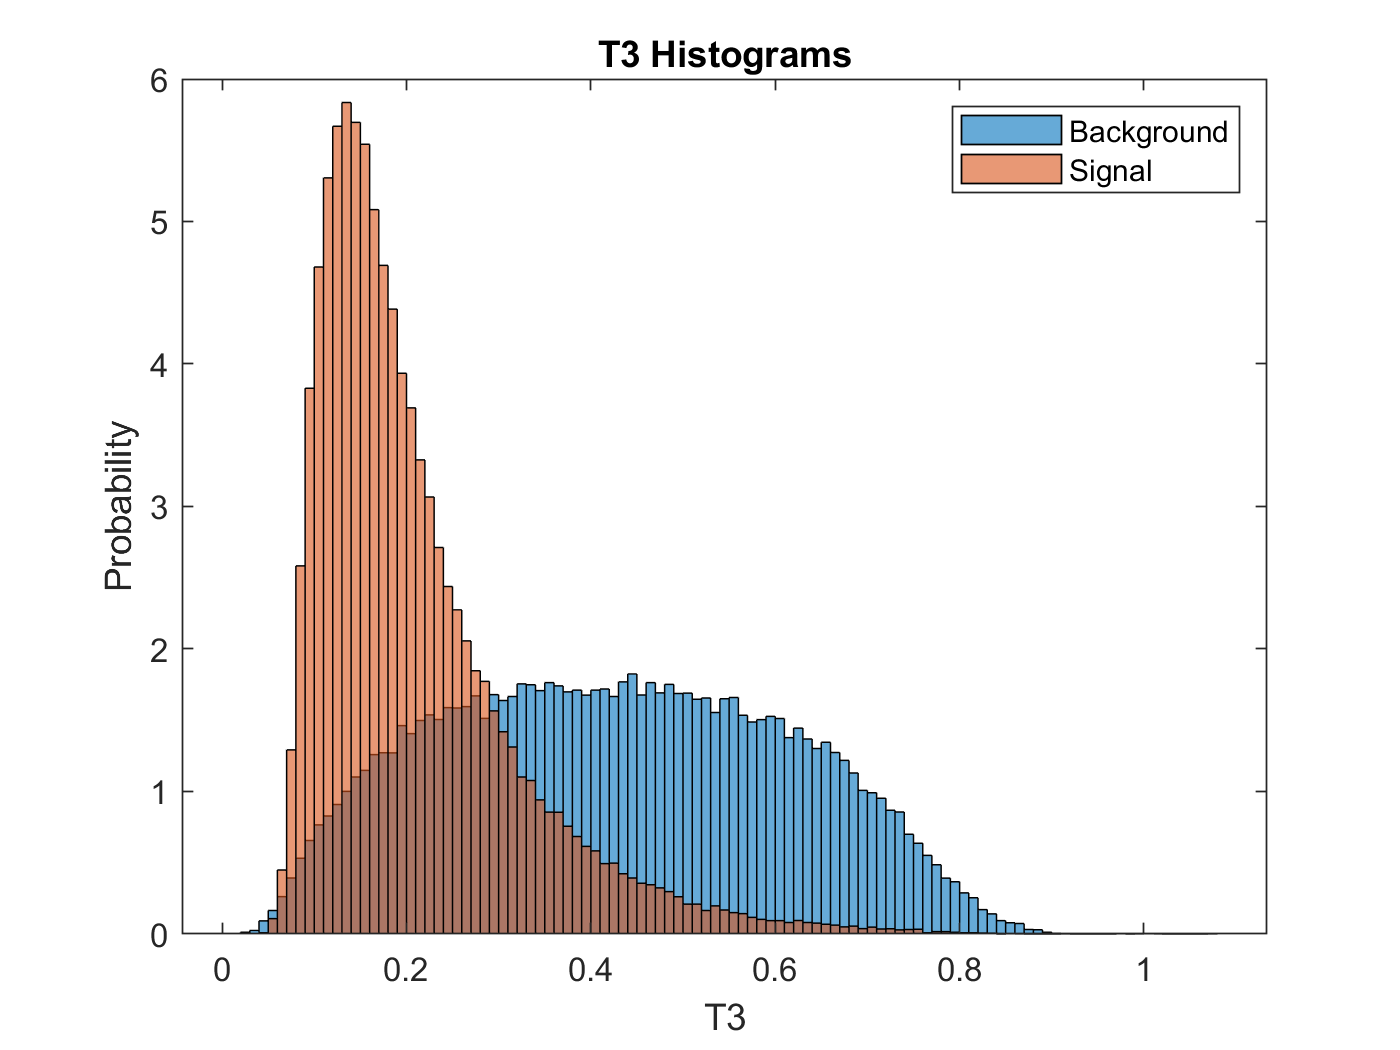

histogram(bgdata1(11,:),"Normalization","pdf"), hold on, histogram(signaldata1(11,:),"Normalization","pdf");
title("T3 Histograms"), xlabel("T3"), ylabel("Probability");
legend("Background","Signal");
hold off;

The T3 signal is sharply peaked at 0.14 while the background forms a shallower and nearly symmetric hill centered at 0.4. Both form smooth curves and fall within the range of 0 to 1.

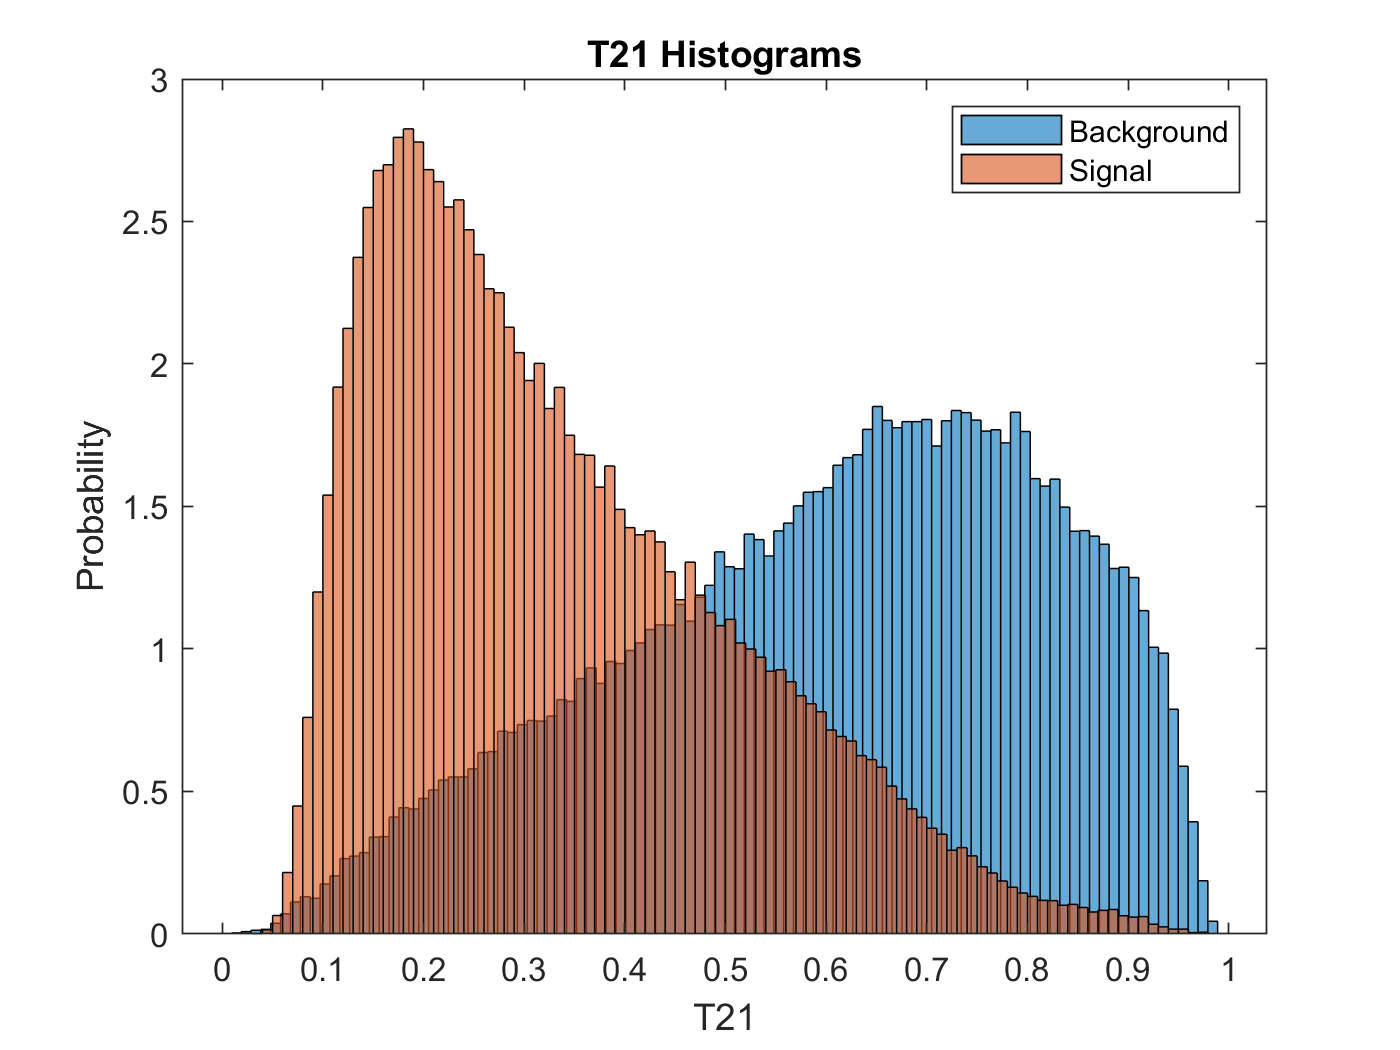

histogram(bgdata1(12,:),100,"Normalization","pdf"), hold on, histogram(signaldata1(12,:),"Normalization","pdf")
title("T21 Histograms"), xlabel("T21"), ylabel("Probability");
legend("Background","Signal");
hold off;

The T21 histograms appear distributed around different means with gradual decaying slopes in opposite directions. They both occupy the same range between 0 and 1 but with starkly different probabilities nearing the ends of the interval.

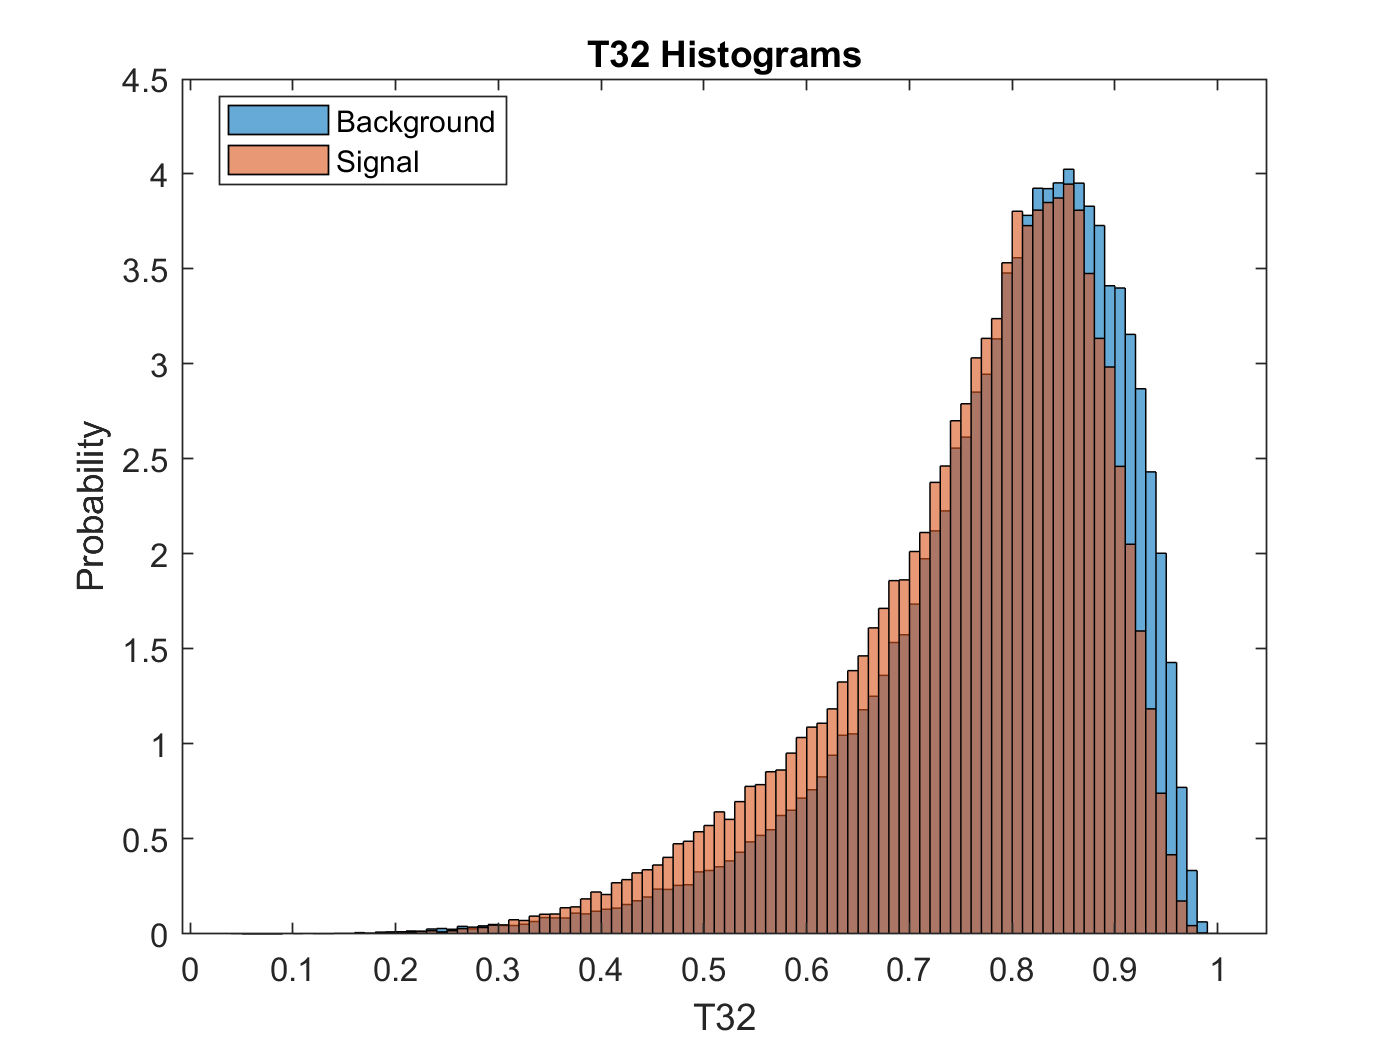

histogram(bgdata1(13,:),"Normalization","pdf"), hold on, histogram(signaldata1(13,:),"Normalization","pdf");
title("T32 Histograms"), xlabel("T32"), ylabel("Probability");
legend("Background","Signal","location","best");
hold off;

The T32 histograms nearly overlap. There is only a very small difference between them.

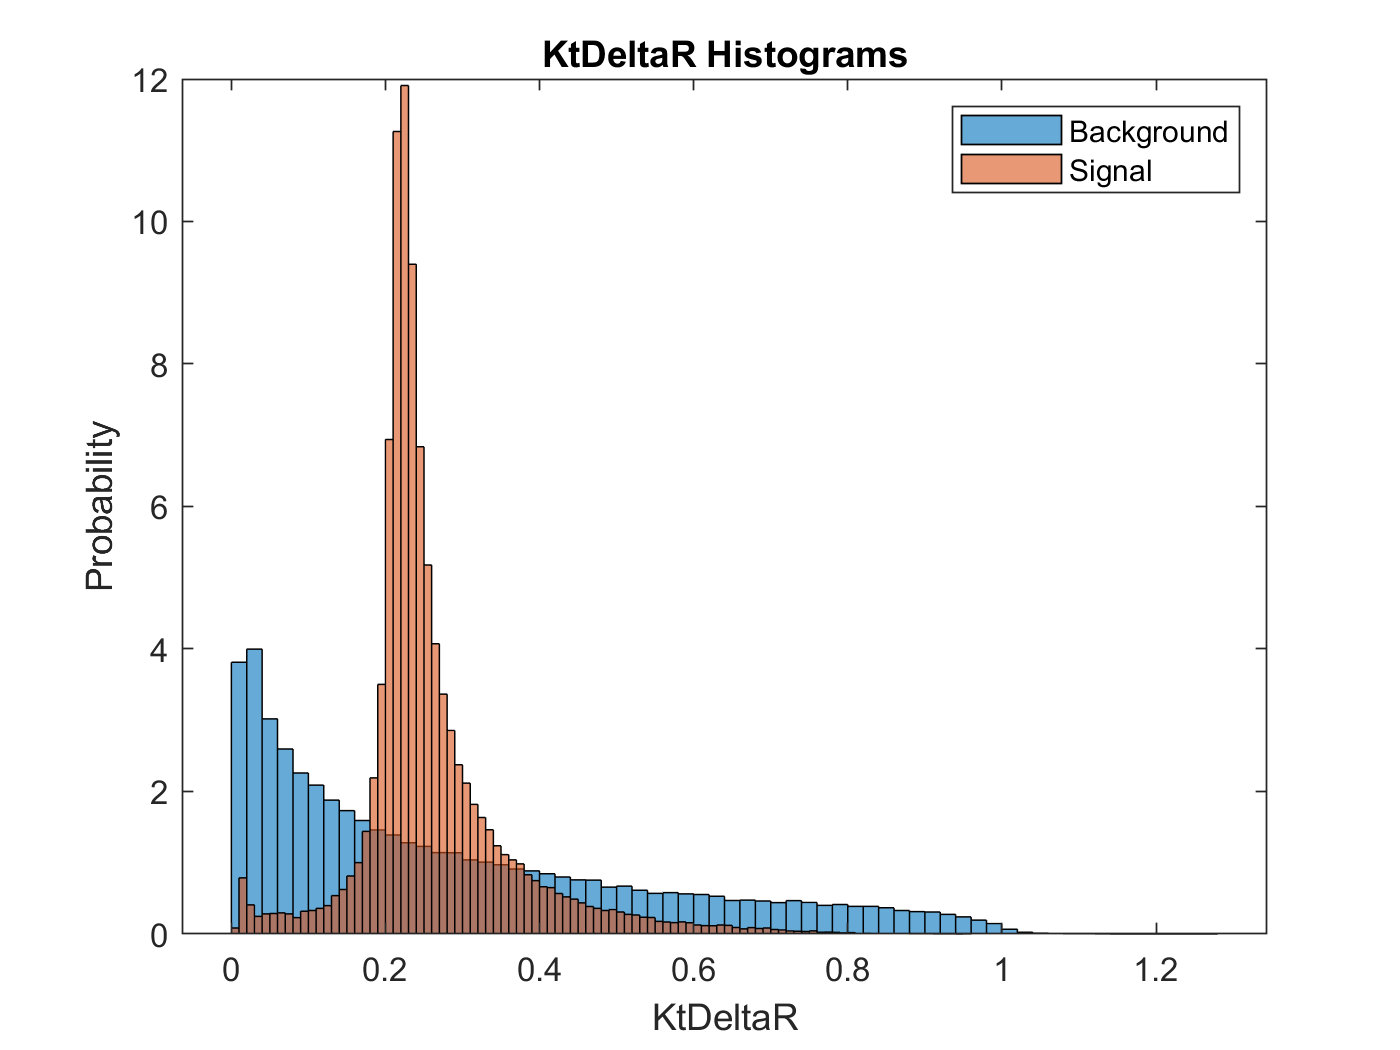

histogram(bgdata1(14,:),"Normalization","pdf"), hold on, histogram(signaldata1(14,:),"Normalization","pdf")
title("KtDeltaR Histograms"), xlabel("KtDeltaR"), ylabel("Probability");
legend("Background","Signal");
hold off;

The KtDeltaR signal is very sharply peaked at 0.22 while the background decays gradually from 0 to just beyond 1.

For nearly every signal histogram compared to the background we can identify some discriminating features. However, there is considerable overlap of the signal and background distributions such that the background is likely to often produce the feature values we are looking for, so no single feature can accurately pinpoint a Higgs jet.

We will need to devise a method of trimming ineligible candidates or combining features for greater discriminatory power. It is unlikely, for instance, that that a Higgs jet will much greater or less than 125 GeV, so we may choose not to record such events. We can repeat this process, checking each of the 14 features, to begin creating a list of likely Higgs jets. 

---

In addition to simple histograms we may also plot variables against each other. This may reveal even more features. There are a great number of combinations, so we can either brute force them until we find something interesting or do some more reading and try to predict interesting plots. The links in the lab description have some sample plots that do this. A quick example:

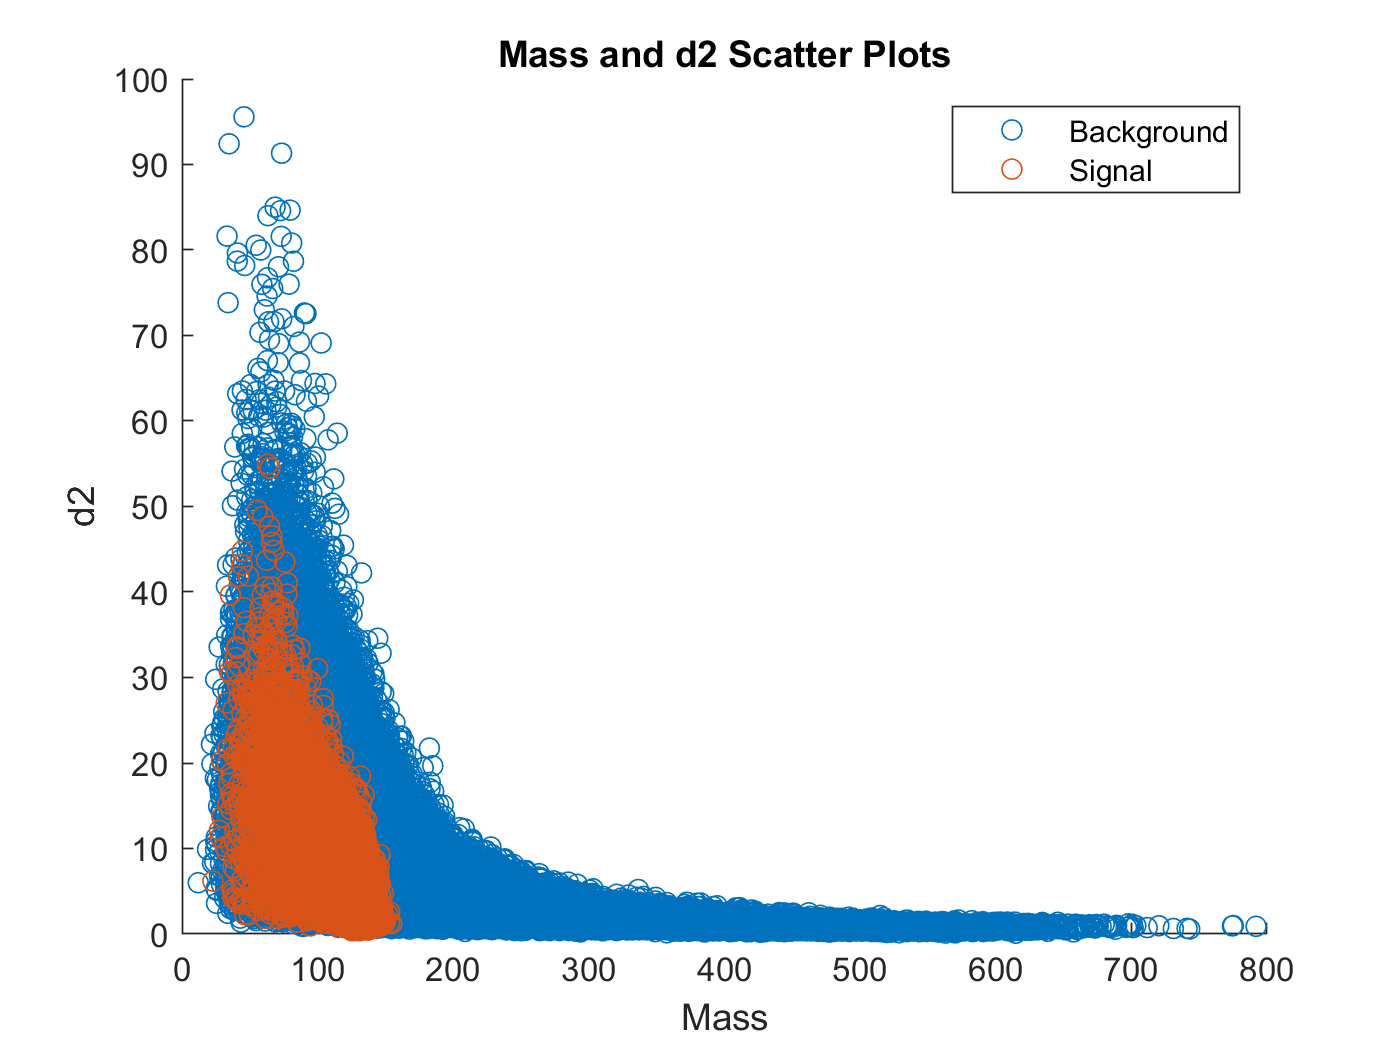

% try: ee2 and mass,
scatter(bgdata1(4,:),bgdata1(7,:)), ylim([0,100]); %xlim([50,200]),
hold on;
scatter(signaldata1(4,:),signaldata1(7,:));
title("Mass and d2 Scatter Plots"), legend("Background","Signal");
xlabel("Mass"), ylabel("d2");
hold off;